## Primjer 1. 4x4 jednostavna matrica


% matrica povezanosti
G = [0 1 1 0; 0 0 1 0; 1 1 0 0; 1 0 1 0];
disp(G)

     0     1     1     0
     0     0     1     0
     1     1     0     0
     1     0     1     0



n = 4;
tol = 1e-5;
maxit = 1000;
v = ones(n,1) / n;
w = v;
alpha = 0.85;
% prvo koristimo klasicni algoritam
[pr, perm, iter] = PageRank(G,v,w,alpha);
disp('Page Rank vector pomocu naseg algoritma:')

Page Rank vector pomocu naseg algoritma:


disp(pr)

    0.2311    0.3134    0.4180    0.0375



disp('Broj iteracija:')

Broj iteracija:


disp(iter)

    14



% drugo, implementacija algoritma bez dangling node-ova (sa predavanja)
[pr, iter] = PageRankNonDangling(G,v,w,1 - alpha,1e-5,1000);
disp('Page Rank vector pomocu algoritma sa predavanja, koji ne uzima u obzir visece vrhove:')

Page Rank vector pomocu algoritma sa predavanja, koji ne uzima u obzir visece vrhove:


disp(pr)

    0.2311
    0.3134
    0.4180
    0.0375



disp('Broj iteracija:')

Broj iteracija:


disp(iter)

    17



## Primjer 2 6x6 Matrica s visecim vrhovima        

% neki kod...
M = [0 1 1 0 1 0; 0 0 0 0 0 0; 1 1 0 0 1 0; 1 0 1 1 0 0; 0 0 0 0 0 0; 0 0 0 1 1 0];
disp(M)

     0     1     1     0     1     0
     0     0     0     0     0     0
     1     1     0     0     1     0
     1     0     1     1     0     0
     0     0     0     0     0     0
     0     0     0     1     1     0



alpha = 0.85;
n = 6;
v = ones(n,1) / n;

% lalic dodaj svoj algoritam
% nekako napravi ovu permutaciju, kao U(perm) samo za ovu matricu
% dodaj to i tu ispod

% Page rank sa vise dangling node vektora v
[pr, perm, iter] = mPageRank(M, v, alpha, [0 1/3 1/3 0 0 1/3; 1/2 0 0 0 1/2 0]');
disp('Page rank algoritam koji uzima vise od jednog "dangling node vektora" w');

Page rank algoritam koji uzima vise od jednog "dangling node vektora" w


disp(pr)

    0.1856    0.0863    0.1757    0.0824    0.2632    0.2068



disp('Broj iteracija:')

Broj iteracija:


disp(iter)

    17



## Primjer 3. Crawler web-matrica

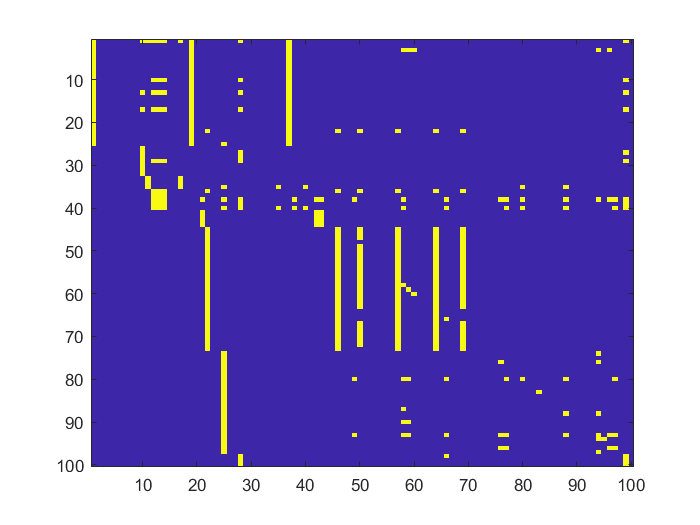

% matrice dobivene pomoću crawler algoritma
load('reddit_domain_G.mat');
load('reddit_domain_U.mat');
n = 100;
v = ones(n,1) / n;
w = v;
alpha = 0.15;
figure(1)
imagesc(G)


% Page Rank
[pr, perm, iter] = PageRank(double(G)', v, w, alpha);
pageRank = pr';
imeStranice = U(perm);
tbl=table(pageRank,imeStranice);
disp(sortrows(tbl,{'pageRank'},{'descend'}))

    pageRank                  imeStranice             
    _________    _____________________________________

     0.015371    'https://www.facebook.com'           
     0.015098    'https://www.instagram.com'          
     0.013015    'https://instagram.com'              
     0.012488    'https://twitter.com'                
     0.011946    'https://www.youtube.com'            
     0.011477    'https://schema.org'                 
     0.011172    'https://www.reddit.com'             
     0.011129    'https://mp.weixin.qq.com'           
     0.011086    'https://creativecommons.org'        
     0.010815    'https://wordpress.org'              
     0.010491    'https://www.microsoft.com'          
     0.010422    'https://www.redditinc.com'          
     0.010422    'https://www.redditgifts.com'        
     0.010314    'https://s.imgur.com'                
     0.010314    'https://quantcast.mgr.consensu.or

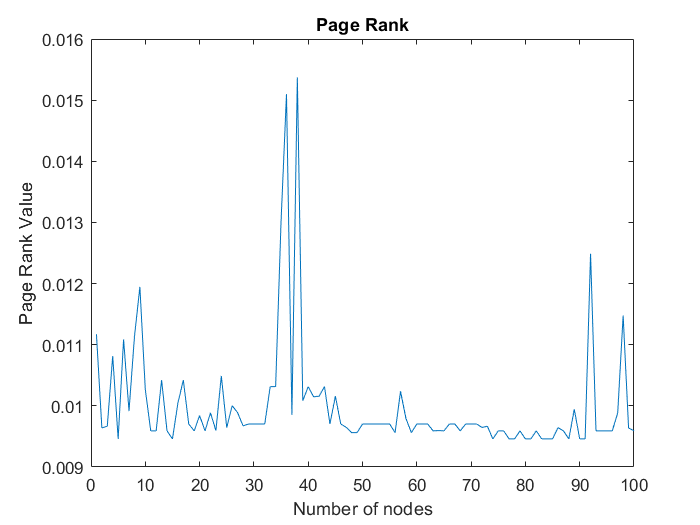

figure(2)
plot(pr)
title('Page Rank');
xlabel('Number of nodes')
ylabel('Page Rank Value')


% vise dangling node vectora...
m = 20;
w = generateDanglingNodeVector(n, m);
[pr, perm, iter] = mPageRank(double(G)', v, 1 - alpha, w);
pageRank = pr';
imeStranice = U(perm);
tbl=table(pageRank,imeStranice);
disp(sortrows(tbl,{'pageRank'},{'descend'}))

     pageRank                  imeStranice             
    __________    _____________________________________

       0.46078    'https://www.instagram.com'          
       0.46078    'https://instagram.com'              
      0.078316    'https://mp.weixin.qq.com'           
    1.3278e-05    'https://www.facebook.com'           
    3.2811e-06    'https://www.youtube.com'            
    3.2775e-06    'https://twitter.com'                
     3.096e-06    'https://schema.org'                 
    2.4858e-06    'https://www.reddit.com'             
     2.214e-06    'https://wordpress.org'              
    2.1791e-06    'https://www.microsoft.com'          
    1.8345e-06    'https://www.redditinc.com'          
    1.7875e-06    'https://creativecommons.org'        
    1.6537e-06    'https://m.imgur.com'                
    1.6333e-06    'https://imgur.com'                  
    1.6125e-06    'https://www.redd

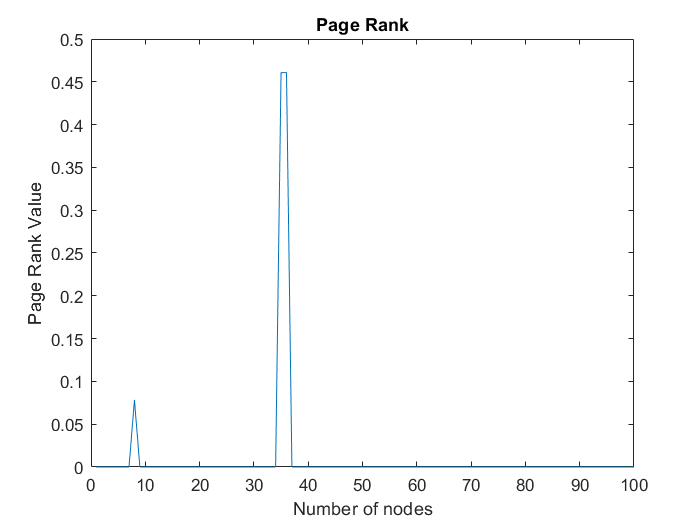

figure(2)
plot(pr)
title('Page Rank');
xlabel('Number of nodes')
ylabel('Page Rank Value')

## Google webGraph - Primjer sa Kaggle-a

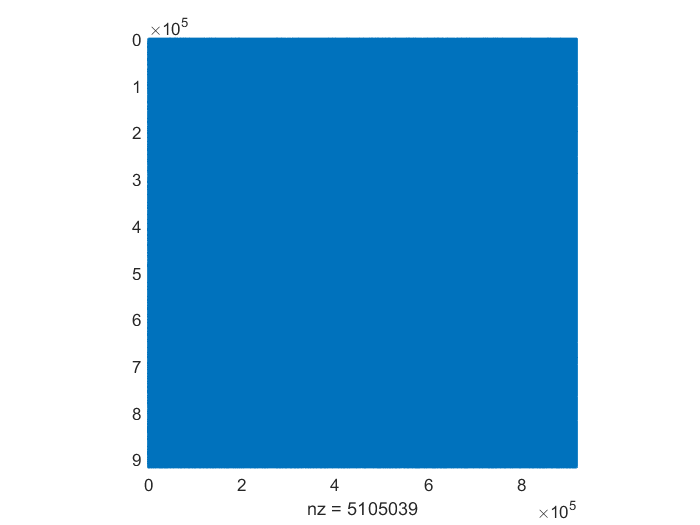

%H = readFromFile();
n = 916428;
edges = 5105039;
%G = makeGoogle(H, edges);
load('VelikiG.mat');


v = ones(n,1) / n;
w = v;
alpha = 0.2;

a = formVector_a(G);
dD = sparseDiagInverse(G * ones(n, 1));
[x, k] = powerMethod(dD', G, ones(1,n) / n, alpha, a, ones(n,1) / n, tol, maxit);

disp('Norma izracunatog PageRank vektora:')

Norma izracunatog PageRank vektora:


disp(norm(x,1))

    1.0000



disp('Broj iteracija:')

Broj iteracija:


disp(k)

     4



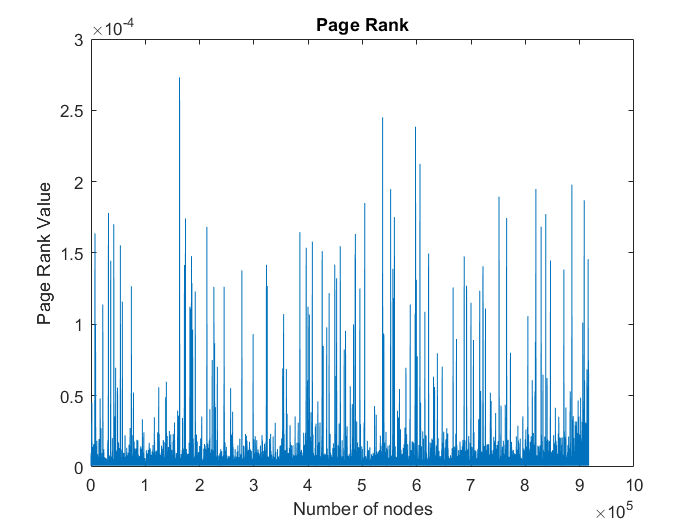


figure(4)
plot(x)
title('Page Rank');
xlabel('Number of nodes')
ylabel('Page Rank Value')